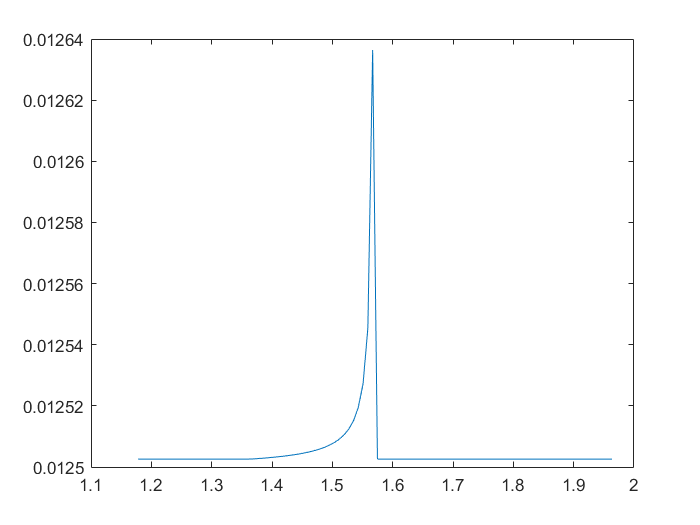

%This is the main script
n = 100; %number of data points
theta = linspace(3*pi/8, 5*pi/8, n); %Ramp Angle, radians
v = 20; % Turn Velocity of the vehicle (Tangential) m/s
R = 7; % Turn Radius (from center of turn to center of vehicle) meters

torqueOutputs = zeros(3,n); %Initialize the output array

for i = 1:n
    %Loop over the calcTorque function to calculate T2, T3 and isFpre for
    %each theta
    [T2, T3, Fpre] = calcTorque(R, v, theta(i));
    torqueOutputs(1, i) = T2;
    torqueOutputs(2, i) = T3;
    torqueOutputs(3, i) = Fpre;
    
end

T2array = torqueOutputs(1, :);
T3array = torqueOutputs(2, :);
FpreBoolArray = torqueOutputs(3, :);

%Plotting the outputs, y-axis is the torque and x-axis is the ramp angle in
%radians
plot(theta, T2array)

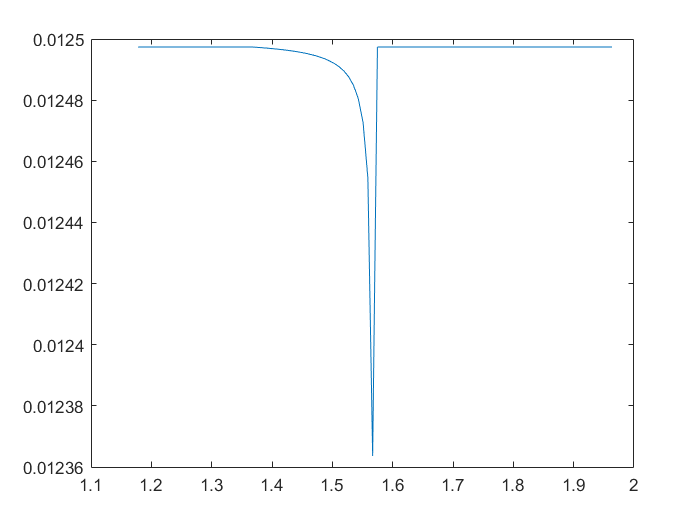

plot(theta, T3array)